# Observer design and MATLAB tools 

The control101 toolbox focuses mainly on linear models and thus simple MATLAB code is sufficient to illustrate the core behaviours and analysis. A common linear model type is the state space model. 

When a system is expressed as a state space model, it is normal to design the closed-loop compensator as a state feedback but this assumes that the states are known. In practice the states are not known and need to be inferred or estimated from available measurements; an observer is used for this process. This file introduces the concept of the observer quickly and then focuses on how to use MATLAB to support his approach. As ever, use text books for more detail on the theoretical aspects.

This file has relatively few examples as it makes more sense to use simulink to investigate issues such as tracking and rejecting uncertainty and these issues are covered in more detail in later files (e.g. ***state_space_and_simulinkfile1_control101, state_space_and_simulinkfile2_control101, state_space_and_simulinkfile3_control101***).

Lots of code snippets are provided as examples of how MATLAB can be used and the intention is that readers can use these as exemplars and/or templates and change the models and scenarios for their own need.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, Ross Drummond, Lanlan Su (University of Sheffield) and Ruth Bars ( Budapest University of Technology and Economics)                             

## Table of Contents

- Background on state observer design

- Examples of observer design with MATLAB

- The impact of an observer on closed-loop behaviour

- The impact of parameter uncertainty

## 1. Background on state observer design

Here assume a state space model of the form:

$\dot{X} =A\;X+B\;U;\;Y=C\;X+D\;U+d,\;$ (1.1)

with state *X*, input *U* and output *Y *and* d *represents an ouput disturbance*. *Here assume that *D*=0*. *The core point here is that the measurement is usually available for the outputs* Y* and not of the states. Hence, one might ask, how do we implement a state feedback controller?

$U=-K\;X$    (1.2)

Clearly, in place of the actual states  *X*, we will need to use estimates for those values, so for example $U=-K\;Z$, but where do those estimates *Z* come from? This is the purpose of an observer, to produce reliable estimates which are effective in the feedback law.

It is not the purpose of this note to re-derive all the theory behind observers, nor to explain the commonly accepted structure; readers should refer to the text books for more theoretical background. Instead this resource presents the most popular solution and moves on from there.

- Define a model (observer) for the process: $\dot{Z} =A_m \;Z+B_m \;U;{\;\;\;\;Y}_m =C_m Z,\;$

- The model is run in parallel with the real process and the hope is that, given they have the same input, as long as $A_m \approx A,B_m \approx B,C_m \approx C$, then over time the model state *Z* will have the same value as the system state *X*.

For many reasons, the above two bullet points are not enough because the real process will not match the model due to parameterisation errors, non-linearities, disturbances and more. Hence, we need to correct the observer state to encourage it to move towards the true state value. Consequently, a common solution is to modify the observer equation to the following.


$$\dot{Z} =A_m \;Z+B_m \;U+L\left(Y-Y_m \right);{\;\;\;\;Y}_m =C_m Z,\;$$


that is,  measure the error between the model output and true process output and include this in the same manner as a feedback term.

### 1.1 Nominal case

If for now we assume that the model and the process are exactly the same, then the observer model can be updated as follows:

$\dot{Z} =A\;Z+B\;U+L\left(Y-C\;Z\right)\;\Rightarrow \dot{Z} =\left(A-\textrm{LC}\right)Z+\textrm{BU}+LY\;\;;$ where *Y* is the output measurement. Next, write this in error form, that is looking for the error between *X* and Z.


$$\dot{X} -\dot{Z} =A\left(X-Z\right)+L\;C\left(\;X-Z\right)\;\Rightarrow \dot{E} =\left(A-\textrm{LC}\right)E;$$


In the nominal case therefore, the observer dynamics have poles given as the eigenvalues of $\left(A-L\;C\right)$. A first task then is to define the matrix *L* so that the observer dynamics have suitable behaviour, that is, the states *Z* converge in a desirable time and fashion. It would be common to target observer dynamics significantly faster than the system dynamics because we do not want to be using erroneous state estimates in the control law $U=-K\;Z$.

### 1.2. Combining the feedback and observer dynamics and separation principle

In practice we have two feedback terms, one from the state feedback and one from the observer. Hence the overall model can be expressed using the following. For now assume no modelling errors.


$$\left\lbrace \dot{X} =A\;X-B\;K\;Z;\;Y=C\;X\right\rbrace ,\left\lbrace \dot{Z} =\left(A-L\;C\right)Z-B\;K\;Z+L\;C\;X\right\rbrace \;$$


For convenience combine these into a single large state space model:


$$\left\lbrack \begin{array}{c}
\dot{X} \\
\dot{Z} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
A & -B\;K\\
L\;C & A-L\;C-B\;K
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
X\\
Z
\end{array}\right\rbrack$$


Next, use a simple transformation matrix *T* to show a decoupling of the feedback and observer designs is reasonable so they can be be carried out independently. That is the closed-loop poles with both a state feedback and an observer reduce to the poles of *(A-BK)* and *(A-LC)*.


$$\left\lbrace T=\left\lbrack \begin{array}{cc}
I & 0\\
I & -I
\end{array}\right\rbrack ;\;T^{-1} =T\right\rbrace \;\;\;\Rightarrow \;\;T\left\lbrack \begin{array}{cc}
A & -\mathrm{BK}\\
\mathrm{LC} & A-\mathrm{LC}-\mathrm{BK}
\end{array}\right\rbrack T^{-1} =\left\lbrack \begin{array}{cc}
A-\mathrm{BK} & \mathrm{BK}\\
0 & A-\mathrm{LC}
\end{array}\right\rbrack$$


**Remark**: Clearly in the real case, with uncertainty, this analysis breaks down to some extent but that is beyond the remit of this series of resources. In such a case (assume real process still linear) one would have the two models below and *K, L* would be designed using the model parameters.


$$\left\lbrace \dot{X} =A\;X-B\;K\;Z;\;Y=C\;X\right\rbrace ,\left\lbrace \dot{Z} =\left(A_m -L{\mathrm{C}}_m \right)Z-B_m \;K\;Z+L\;C\;X\right\rbrace \;$$


### 1.3 Designing the observer matrix L using duality

There are a number of resources discussing the design of a state feedback controller to give good dynamics to the system with state transition matrix *(A-BK)*,  ***state_feedback_control101, optimal_state_feedback_control101.  *** Hence the obvious first thought is to ask whether these could be used in determining a suitable value for *L* which will give good dynamics to a system with state transition matrix *(A-LC)*.

First note that the eigenvalues/dynamics of a system are not affected by transposition and thus we could equally seek to design $L^T$ for the system with matrix: $A^T -C^T L^T$. This now has the same structure as (*A-BC*).

**Proposal**: Whatever design methods used to determine *K*  for closed-loop dynamics $\dot{X} =\left(A-B\;K\right)\;X$ can equally be used to determine $L^T$ for the closed-loop dynamics $\dot{Z} =\left(A^T -C^T L^T \right)Z$. Simple replace: $A\to A^T ,B\to C^T ,K\to L^T \ldotp$

### 1.4 Possible observer design methods

First we should be clear that the most popular observer design method is the Kalman filter, but that requires more explanation and detail which is not appropriate to this specific resource and so readers are advised to read up on that elsewhere. Critically, it is based on a careful description/modelling of the uncertainty which is not assumed available here.

Consequently, this resource proposes two introductory and simple methods that can be used to get started which are thus consistent with a first course in control.

- Use pole placement (***state_feedback_control101). ***As explained earlier this has the weakness that one needs to be able to define all the desired poles, although for an observer we want the poles to be much faster than open-loop.

- Use an analogue to optimal control (***optimal_state_feedback_control101)***, although the definition of suitable weighting matrices *Q *and *R* may not be immediately obvious.

Code to illustrate both approaches and the usage alongside a state feedback is given below.

## 2. Examples of observer design with MATLAB

The code below demonstrates two alternative methods for finding an observer, with MATLAB doing the work using built in functions. A reminder that you need to check for observability because without this a design may not be possible and certainly many design methods would fail.

### 2.1 Observer design using pole placement

These examples show that simple pole placement methods are possibly by simply transposing the relevant matrices first. The rank statement emphasises the need to ensure the system is observable. Here the code uses ***acker.m*** and ***place.m*** to emphasise, that as expected in most cases, both approaches give the same results. Here the choice of poles is arbitrary and indeed, in general as with pole placement, the choice of poles is difficult to systemise without further assumptions and design methods.

disp('Section 2.1')

Section 2.1


disp('Example 1');

Example 1


A=[-0. -0.4 -0.6 0.2;0.4 1 .7 .5;-0.3 1 1 0;0.8 1.1 -0.3 0]; 
B=[1;1;0;-1];
C=[3 2 0 1];
Mo=ctrb(A',C');
check_rank_is_4 =rank(Mo)

check_rank_is_4 = 4

L=acker(A',C',[-0.6 -1 -1.2 -0.7]);
L=L';
check_observer_poles = eig(A-L*C)

check_observer_poles =    -1.2000
   -1.0000
   -0.7000
   -0.6000



disp('Example 2');

Example 2


A=[-6 -11 -6;1 0 0;0 1 0]; 
B=[1;0;0];
C=[2 3 5];
Mo=ctrb(A',C');
check_rank_is_3 = rank(Mo)

check_rank_is_3 = 3

L=place(A',C',[-3 -4 -5]);
L=L';
check_observer_poles = eig(A-L*C)

check_observer_poles =    -5.0000
   -4.0000
   -3.0000


### 2.2 Observer design using LQR

The main interest here is to explore the choices for Q and R which underpin this design method as one difficultly with an LQR approach is the selection of the weights. This resource uses unitary weights for simplicity and demonstrates that a working observer can be determined, albeit with less influence over the speed of the poles.

disp('Section 2.2')

Section 2.2


disp('Example 1');

Example 1


A=[-0. -0.4 -0.6 0.2;0.4 1 .7 .5;-0.3 1 1 0;0.8 1.1 -0.3 0]; 
B=[1;1;0;-1];
C=[3 2 0 1];
L=lqr(A',C',eye(4),1);
L=L';
check_observer_poles = eig(A-L*C)

check_observer_poles =   -3.8908 + 0.0000i
  -1.8171 + 0.0000i
  -0.4705 + 0.1078i
  -0.4705 - 0.1078i



disp('Example 2');

Example 2


A=[-6 -11 -6;1 0 0;0 1 0]; 
B=[1;0;0];
C=[2 3 5];
L=lqr(A',C',eye(3),1);
L=L';
check_observer_poles = eig(A-L*C)

check_observer_poles =   -7.3952 + 0.0000i
  -1.4695 + 1.8719i
  -1.4695 - 1.8719i


## 3. The impact of an observer on closed-loop behaviour

The observer is used to estimate states, so during transients there will inevitably be some errors. These errors will in turn impact on the efficacy of the feedback. The examples below illustrate the differences between closed-loop regulation behaviour with no state estimation errors and behaviour with an observer. 

The user should change the lines where the poles are decided to investigate the impact on the behaviour of  the target pole positions for both the state feedback and the observer.

disp('Section 3 - the impact of the observer on closed-loop behaviour')

Section 2.3 - the impact of the observer on closed-loop behaviour


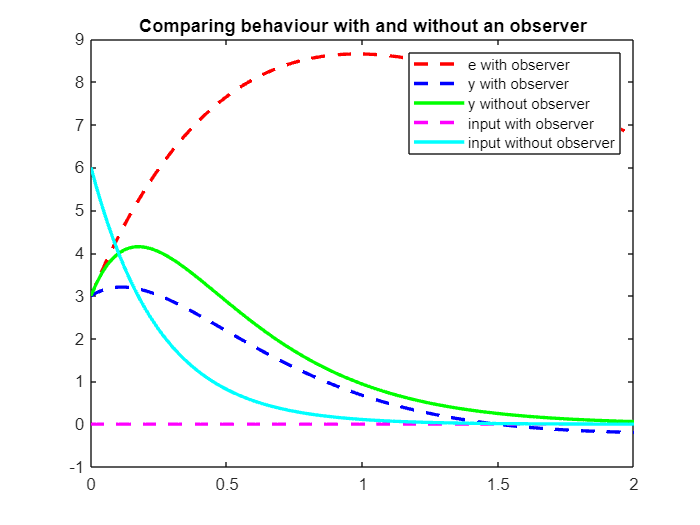

A=[-6 -11 -6;1 0 0;0 1 0]; 
B=[1;0;0];
C=[2 3 5];
L=place(A',C',[-1,-0.8,-0.5]);  % pole placement with observer
K=place(A,B,[-2 -3 -4]);        % pole placement with state feedback
L=L';
Ac=[A,-B*K;L*C,A-B*K-L*C];
x0=[2;-2;1;0;0;0];
x=[];X=[];y=[];e=[];Y=[];u=[];U=[];
t=linspace(0,2,100);
for k=1:length(t);
    X(:,k)=expm((A-B*K)*t(k))*x0(1:3);
    x(:,k)=expm(Ac*t(k))*x0;
    y(k)=C*x(1:3,k);
    e(k)=[C,-C]*x(:,k);
    Y(k)=C*X(:,k);
    u(k)=-K*x(4:6,k);
    U(k)=-K*X(:,k);
end
plot(t,e,'r--',t,y,'b--',t,Y,'g',t,u,'m--',t,U,'c','linewidth',2);
legend('e with observer','y with observer','y without observer','input with observer','input without observer');
title('Comparing behaviour with and without an observer')

## 4. The impact of parameter uncertainty

Given that there is a separate model for the observer, and one to represent the true process, it is relatively straightforward to form responses with and without parameter uncertainty, as shown in the code below. Use subscript 'm' to denote the model parameters which may differ from the true process parameters. All the design steps are done using the model.

This code is provided as a template so users can investigate scenarios of their own. Here the uncertainty and trajectory differences are small.

disp('Section 4 - the impact of the observer on closed-loop behaviour with uncertainty')

Section 4 - the impact of the observer on closed-loop behaviour


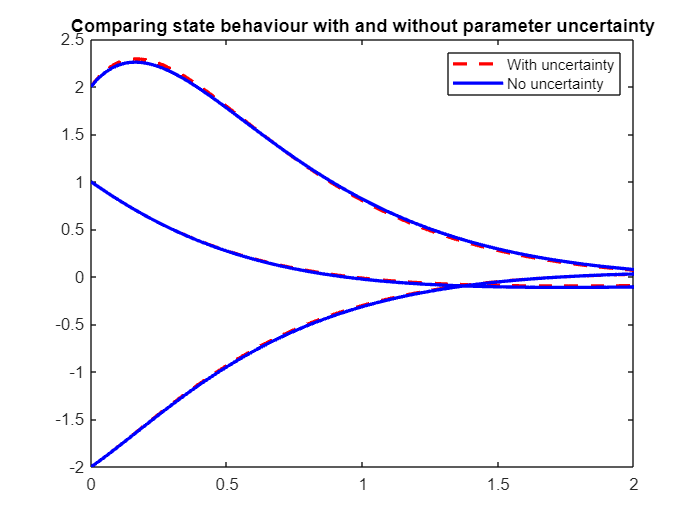

A=[-6 -11 -6;1 0 0;0 1 0]; B=[1;0;0]; C=[2 3 5];             % true process
Am=[-6 -11 -6.4;1 0 0;0 1 0]; Bm=[1.2;0;0]; Cm=[2.4 2.8 5];  % Assumed model

L=place(Am',Cm',[-1,-0.8,-0.5]);  % pole placement with observer
K=place(Am,Bm,[-2 -3 -4]);        % pole placement with state feedback
L=L';
Ac=[A,-B*K;L*C,Am-Bm*K-L*Cm];      % uncertain case
Ac0=[Am,-Bm*K;L*Cm,Am-Bm*K-L*Cm];  % Nominal case
x0=[2;-2;1;0;0;0];
X=[];Y=[];U=[];X0=X;
t=linspace(0,2,100);
for k=1:length(t);
    X(:,k)=expm(Ac*t(k))*x0;
    X0(:,k)=expm(Ac0*t(k))*x0;
    Y(:,k)=C*X(1:3,k);
    Y0(:,k)=Cm*X0(1:3,k);
end
plot(t,X(1,:)','r--',t,X0(1,:)','b-',t,X(2:3,:)','r--',t,X0(2:3,:)','b-','linewidth',2);
legend('With uncertainty','No uncertainty');
title('Comparing state behaviour with and without parameter uncertainty')

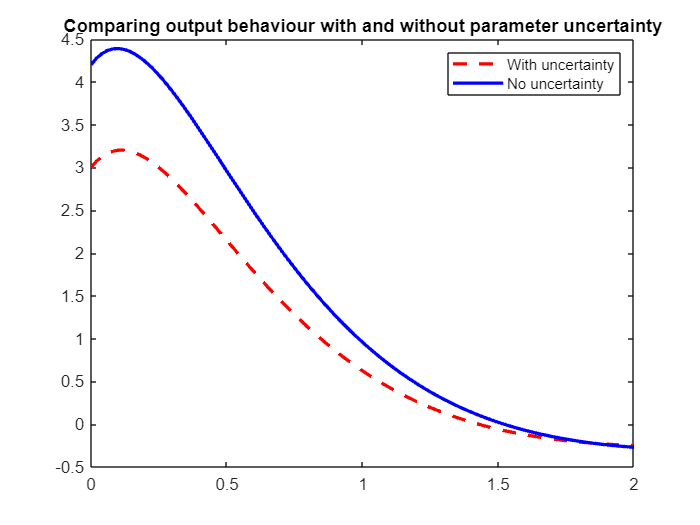

plot(t,Y','r--',t,Y0','b-','linewidth',2);
legend('With uncertainty','No uncertainty');
title('Comparing output behaviour with and without parameter uncertainty')